close("all"); clear; clc;
setmadsympath();

## Sharp model parameters

Cdelta = 12.6738;
Cf1 = 11174;
Cf2 = 938.6;
Cr1 = 15831;
Cr2 = 1325.6;
Ibxx = 11;
Ibxz = -3;
Ibzz = 14;
Ihxx = 1.341;
Ihzz = 0.4125;
a = 0.7427;
af0 = 0.02;
an = 0.2311;
ar0 = 0.02;
b = 0.81;
e = 0.0244;
f = 0.0283;
g = 9.80665;
h = 0.532;
ify = 0.484;
iry = 0.638;
mb = 257.06;
mh = 24.24;
rf = 282E-03;
rr = 297E-03;
tf = 50E-03;
tr = 70E-03;
caster = deg2rad(24);

## Normal forces

Zr = 1.428E03;
Zf = 1.005E03;

## Tire coefficients

Longitudinal :

kkf = 20;
kkr = 20;

Lateral :

kaf = Cf1/Zf;
klf = Cf2/Zf;
kar = Cr1/Zr;
klr = Cr2/Zr;

## Longitudinal displacement

p = b + (a - an)/cos(caster);
fw0 = (0.0085 + 0.018/p);
fw2 = 1.59E-06/p;

## Pryde parameters

params = @(v)[
    Cdelta;
    Ibxx;
    Ibxz;
    Ibzz;
    Ihxx;
    Ihzz;
    v;
    Zf;
    Zr;
    a;
    af0;
    an;
    ar0;
    b;
    e;
    f;
    fw0;
    fw2;
    g;
    h;
    ify;
    iry;
    kaf;
    kar;
    kkf;
    kkr;
    klf;
    klr;
    mb;
    mh;
    rf - tf;
    rr - tr;
    tf;
    tr;
    caster
    ];

## Model

nv = 1000;
vx = linspace(50,130,nv)./3.6;
plant = @prydeMotorcycleLateralStateSpace;
f = @(v)plant(params(v));
sys = arrayfun(f,vx.',"uniform",0);

## Nyquist plot

poles = cellfun(@pole,sys,"uniform",0);
poles = cell2mat(poles);

Plot poles over speed :

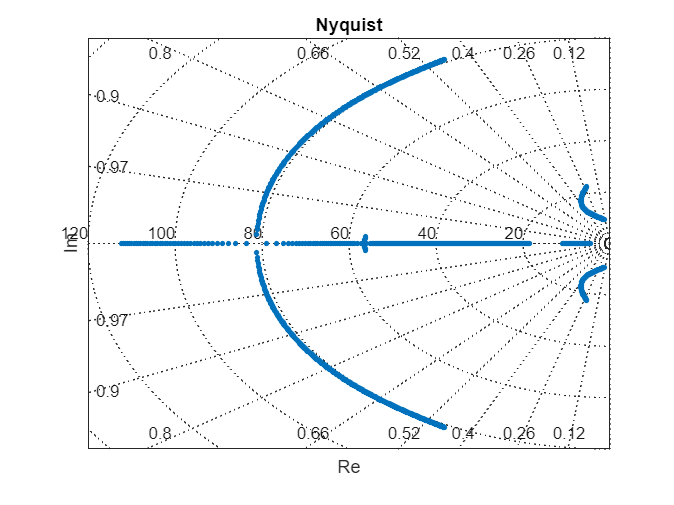

fig = figure();
axe = axes(fig);

scatter(axe,real(poles),imag(poles), ...
    10, ...
    "filled" ...
    );

xticks(axe,[]);
yticks(axe,[]);
title(axe,"Nyquist");
xlabel(axe,"Re");
ylabel(axe,"Im");
box(axe,"on");
sgrid(axe);

## BikeSim results

vx = num2str(80);
dpath = "G:\My Drive\BikeSimResults\BigSports\";
spath = "OpenLoop" + vx + "kph\";
fname = "results_big_sports_open_loop_";
load(dpath + spath + fname + vx + "kph.mat");

time = results.Time;
camber = deg2rad(results.Roll);
steer = deg2rad(results.Steer);
wz = deg2rad(results.AVz);
vy = results.VyW0_2./3.6;
wx = deg2rad(results.AVx);
ws = deg2rad(results.M_StrSys./0.2212);

s = (180/pi).*[1,1,1,0,1,1] + [0,0,0,1,0,0];
x_mes = s.*[camber,steer,wz,vy,wx,ws];

Mz = results.M_Str_In;

## Model results

sys80 = plant(params(80));
x_sys80 = s.*lsim(sys80,[0.*Mz,Mz],time);

## State observer

% L = standardLMI(sys80.A,sys80.C,0.001);
% A = sys80.A - L*sys80.C;
% syso = ss(A,sys80.B,sys80.C,0);
% x_est = lsim(syso,[0.*Mz,Mz],time);

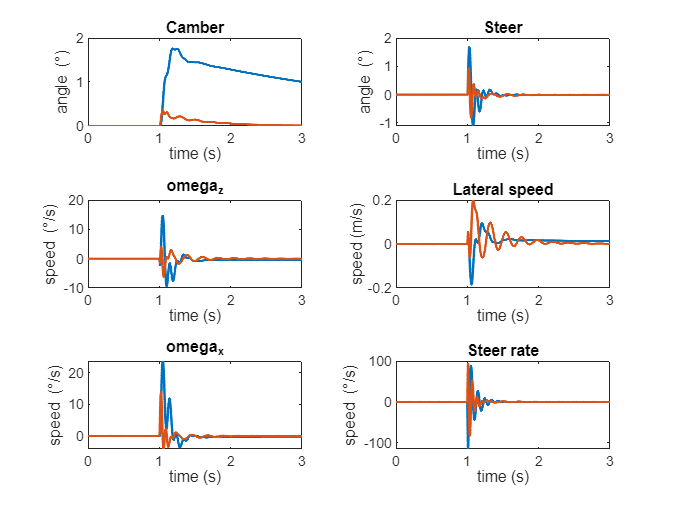

fig = figure();
tl = tiledlayout(3,2,"Parent",fig);

titles = [
    "Camber";
    "Steer";
    "omega_z";
    "Lateral speed";
    "omega_x";
    "Steer rate"
    ];

units = [
    "angle (\circ)";
    "angle (\circ)";
    "speed (\circ/s)";
    "speed (m/s)";
    "speed (\circ/s)";
    "speed (\circ/s)"
    ];

for k = 1:6
    axe = nexttile(k);
    hold(axe,"on");
    plot(axe,time,x_mes(:,k),"LineWidth",1.5);
    plot(axe,time,x_sys80(:,k),"LineWidth",1.5);
    % plot(axe,time,x_est(:,k));
    hold(axe,"off");
    box(axe,"on");
    title(axe,titles(k));
    xlabel(axe,"time (s)");
    ylabel(axe,units(k));
end

function L = standardLMI(A,C,gm)
    arguments
        A (6,6) double;
        C (6,6) double;
        gm (1,1) double;
    end
    yalmip('clear');
    opts = sdpsettings('solver','sdpt3');
    I = eye(size(A));
    P = sdpvar(6,6);
    R = sdpvar(6,6);
    g = 1/(gm^2);

    lmiA = P >= 0;
    lmiB = [
        A.'*P + P*A - R.'*C - C.'*R + I, P;
        P, -g.*I
        ] <= 0;

    cons = [
        lmiA;
        lmiB
        ];

    optimize(cons,0,opts);

    L = value(P)\value(R.');
end